# Solución de circuitos RCL (Homework)

##  Pregunta

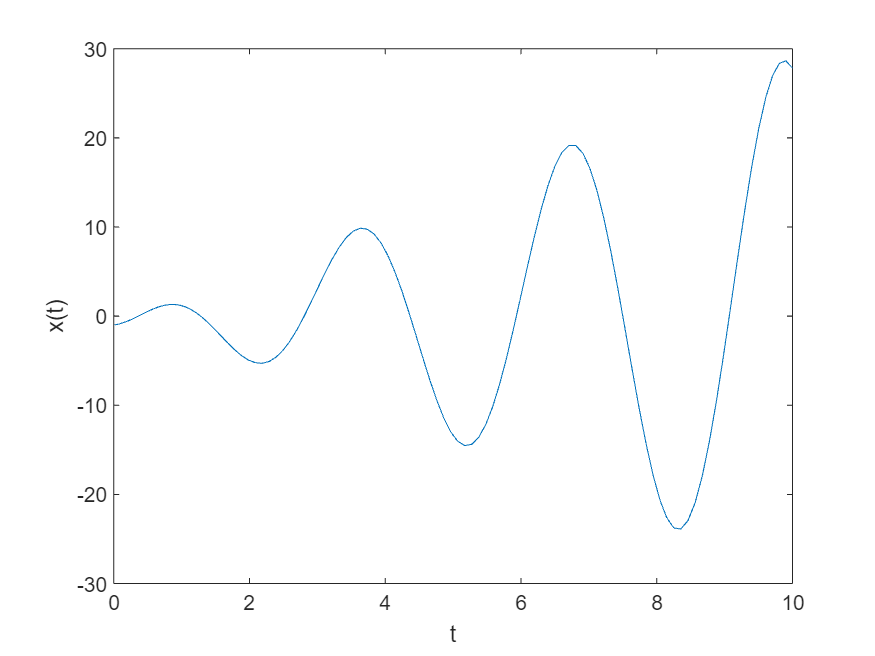

% Define given values
x0 = -1;
dx0 = 1;

% Define differential equation
d2xdt2 = @(t, x, dx) -4 * x - 8 * sin(2 * t) + 9 * cos(2 * t);

% Define function to convert second-order ODE to system of first-order ODEs
f = @(t, y) [y(2); d2xdt2(t, y(1), y(2))];

% Solve system of first-order ODEs using ode45
tspan = [0, 10]; % time interval to solve over
y0 = [x0; dx0]; % initial conditions
[t, q] = ode45(f, tspan, y0);

% Extract solution for x(t)
x = q(:, 1);

% Plot solution
plot(t, x)
xlabel('t')
ylabel('x(t)')



% Display result
charge = q(end);
fprintf('The charge on the capacitor at t = %.2f s is %.4f C\n', t(end), charge);

The charge on the capacitor at t = 10.00 s is -13.9345 C


## Funcion

function q_t = capacitor_charge(L, R, C, E, q0, i0, t)
    % Define the differential equation for charge on the capacitor
    dqdt = @(t, q) (E(t) - R * (1/C) * q - i0) / L;

    % Solve the differential equation using ode45
    [~, q] = ode45(dqdt, [0 t], q0);

    % Get the charge at t and round to four decimal places
    q_t = round(q(end), 4);
end
